# 1

load("id.mat", "c", 'idx') %O/B o/


ans =

  0x0 empty char array



oc = c

oc = 2x5 cell array
    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}
    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}


c = cell(2,10);

d = {'bo', 'ca', 'i', 'tl', 'ld'}

d = 1x5 cell array
    {'bo'}    {'ca'}    {'i'}    {'tl'}    {'ld'}


for r = 1:2
    for co = 1:5
        c{r,co} = oc{r,co};
    end
    for co = 6:10
        c{r,co} = readtable(['cv/10c/0 ' d{ ...
            co-5} '.data'], 'Filetype', 'text');
        if r == 1
            c{r,co}.Ylatitude(:) = c{r, ...
                co}.Latitude(1);
            t = c{r,co};
            c{r,co} = t(2:end,:);
        else
            c{r,co}.Ylatitude(: ...
                ) = c{r,co}.Longitude(1);
            c{r,co}.Properties.VariableNames{ ...
                end} = 'Ylongitude';
            t = c{r,co};
            c{r,co} = t(2:end,:);
        end
    end
end
c

c = 2x10 cell array
    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}
    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}


% idx = randperm(10)
% save("cv/10c/id.mat","idx","c") % ,"q"
% save("/MATLAB Drive/id.mat","c","-append")
load("cv/10c/id.mat")%O/B o/
whos("-file","cv/10c/id.mat") % 1, 4, 5 & 2

  Name      Size                  Bytes  Class     Attributes

  c         2x10                 140240  cell                
  cc        2x10                 812240  cell                
  g         2x10              207701600  cell                
  idx       1x10                     80  double              
  ir        1x1000                 8000  double              



cc{1,1} = [cc{1,idx(1)};c{1,idx(2)}]; cc

cc{1,1} = [cc{1,1};c{1,idx(2)}]; cc

cc = 2x10 cell array
    {300x6 table }    {0x0 double}    {0x0 double}    {0x0 double}    {0x0 double}    {0x0 double}    {0x0 double}    {0x0 double}    {0x0 double}    {0x0 double}
    {  0x0 double}    {0x0 double}    {0x0 double}    {0x0 double}    {0x0 double}    {0x0 double}    {0x0 double}    {0x0 double}    {0x0 double}    {0x0 double}


cc = cell(2,10); ci = [1:10 1:10]

ci =      1     2     3     4     5     6     7     8     9    10     1     2     3     4     5     6     7     8     9    10


for r = 1:2
    for co = 1:10
        cc{r,co} = c{r,idx(ci(co))};
        for k = 1:7
            cc{r,co} = [cc{r,co};c{r,idx(ci( ...
                co+k))}];
        end
    end
end
cc

cc = 2x10 cell array
    {800x6 table}    {800x6 table}    {800x6 table}    {800x6 table}    {800x6 table}    {800x6 table}    {800x6 table}    {800x6 table}    {800x6 table}    {800x6 table}
    {800x6 table}    {800x6 table}    {800x6 table}    {800x6 table}    {800x6 table}    {800x6 table}    {800x6 table}    {800x6 table}    {800x6 table}    {800x6 table}


# Longitude gpr:

% cross-validation: % rng('default')
g = cell(2,10);
tic
for r = 1:2
    for co = 1:10
        [r,co]
        tic
        g{r,co} = fitrgp(cc{r,co}, ... % gprMdll
    cc{r,co}.Properties.VariableNames{end}, ...
    'KernelFunction', 'ardsquaredexponential',...
      'FitMethod','sr','PredictMethod', ...
      'fic','Standardize',1,'Sigma',.002);
        toc
     end
end

ans =      1     1


Elapsed time is 15.386505 seconds.


ans =      1     2


Elapsed time is 13.497323 seconds.


ans =      1     3


Elapsed time is 12.045511 seconds.


ans =      1     4


Elapsed time is 15.039360 seconds.


ans =      1     5


Elapsed time is 14.908062 seconds.


ans =      1     6


Elapsed time is 12.646712 seconds.


ans =      1     7


Elapsed time is 13.631426 seconds.


ans =      1     8


Elapsed time is 8.231451 seconds.


ans =      1     9


Elapsed time is 13.168001 seconds.


ans =      1    10


Elapsed time is 12.510986 seconds.


ans =      2     1


Elapsed time is 10.842872 seconds.


ans =      2     2


Elapsed time is 11.238534 seconds.


ans =      2     3


Elapsed time is 11.260656 seconds.


ans =      2     4


Elapsed time is 13.778317 seconds.


ans =      2     5


Elapsed time is 13.664476 seconds.


ans =      2     6


Elapsed time is 11.150999 seconds.


ans =      2     7


Elapsed time is 11.586683 seconds.


ans =      2     8


Elapsed time is 13.994200 seconds.


ans =      2     9


Elapsed time is 14.668320 seconds.


ans =      2    10


Elapsed time is 13.746053 seconds.


toc

Elapsed time is 13.749040 seconds.


g % fprintf('kfoldLoss = %e's, kfoldLoss( ...

g = 2x10 cell array
    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}
    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}


%     cvgprMdl)); ypred = kfoldPredict(cvgprMdl);

% tic
% save("cv/10c/id.mat","g","-append")
% save("cv/10c/id.mat","cc","-append")
% toc
load("cv/10c/id.mat")%O/B o/ , 'g', 'idx'
% load("cv/10c/id.mat", 'c')%O/B o/ , 'g', 'idx'
whos("-file","cv/10c/id.mat")

  Name      Size                Bytes  Class     Attributes

  c         2x10               140240  cell                
  cc        2x10               812240  cell                
  g         2x10            207701600  cell                
  idx       1x10                   80  double              



ci = [9 10 1:10-1]

ci =      9    10     1     2     3     4     5     6     7     8     9


p = zeros(200,2,10);
ct = cell(2,10);
for r = 1:2
    for co = 1:10 % ypredlo
        ct{r, co} = [c{r,idx(ci(co))};
                     c{r,idx(ci(co+1))}];
        t = ct{r, co};
        p(:,r,co) = predict(g{r,co},t(:, 1: ...
            end-1).Variables);
     end
end

addpath('/MATLAB Drive/Sim');
tr = 201; d1km = zeros(tr-1, 10); d2km = d1km;

## ypredlo'% elo = lo(1)-ypredlo(1)

% ci
for co = 1:10
    for i = 1:tr-1
        [d1km(i, co), d2km(i, co)] = lldistkm( ...
            [ct{1,idx(ci(co))}.Ylatitude(i) ...
            ct{2,idx(ci(co))}.Ylongitude(i)], ...
        [p(i,1,co) p(i,2,co)]);
    end
end

% d1km(1:5,:)
col = 10

col = 10

m = zeros(2, col);
for co = 1:col
    m(1, co) = min(d1km(:, co)*1000);
    m(2, co) = max(d1km(:, co)*1000);
end

f = 10; fi = 1;

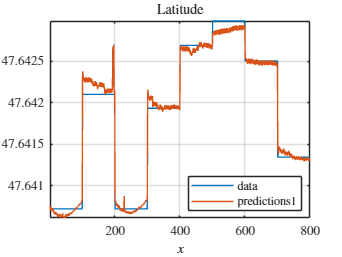

figure()
% plot(sort(cc{1,co}.Ylatitude(:)))
r = 1; t = cc{r,co};plot(t(:, end).Variables/fi);
xlabel('$x$','interpreter','latex'); axis tight
axe()
hold on;
plot(predict(g{r,co},t(:, 1:end-1 ...
    ).Variables)/fi) % ypred
% plot(predict(gt{r,co},t(:, 1:end-1 ...
%     ).Variables)/f)
% t = c{r,idx(ci(co))};k = t(:, end).Variables/fi;
% l = k*ones(1, 4);plot(l(:));
hold off; grid on; % xline(I)
legend({'data','predictions1' ...
    % ,'predictions2' ...
    }, ...
    'Location','Best','interpreter','latex')
title('Latitude','interpreter','latex')

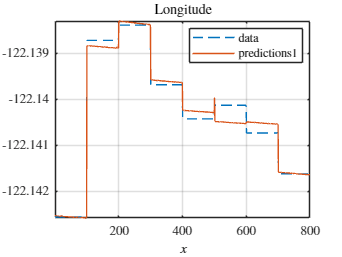

figure()
% plot(sort(cc{1,co}.Ylatitude(:)))
r = 2; t = cc{r,co};
plot(t(:, end).Variables/fi,'--');
xlabel('$x$','interpreter','latex'); axis tight
axe()
hold on;
plot(predict(g{r,co},t(:, 1:end-1 ...
    ).Variables)/fi)
% plot(predict(gt{r,co},t(:, 1:end-1 ...
%     ).Variables)/f)
hold off; grid on; % xline(I)
legend({'data','predictions1' ...
    % ,'p2' ...
    }, ...
    'Location','Best','interpreter','latex')
title('Longitude','interpreter','latex')

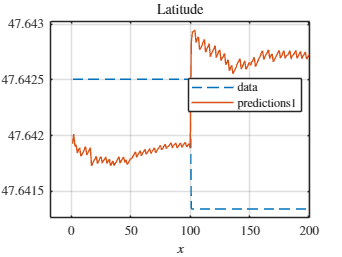

figure()
% plot(sort(cc{1,co}.Ylatitude(:)))
r = 1; co = 5; ci = [5 1:5-1];
t = ct{r,idx(ci(co))};
plot(t(:, end).Variables/fi,'--');
xlabel('$x$','interpreter','latex'); axis tight
axe()
hold on;
plot(p(:, r, co));
% t = cc{r, co}; s = 101:200;
% plot(predict(g{r,co},t(s, 1:end-1 ...
%     ).Variables)/fi)
% plot(predict(gt{r,co},t(s, 1:end-1 ...
    % ).Variables)/f)
hold off; grid on; % xline(I)
% legend({'data','predictions1','p2','p3'}, ...
legend({'data','predictions1' ...
    % ,'p2' ...
    }, ...
    'Location','Best','interpreter','latex')
title('Latitude','interpreter','latex')

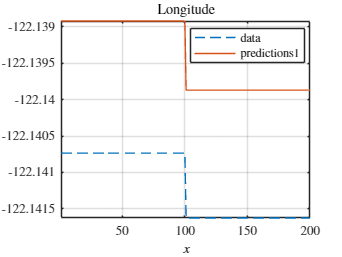

figure()
% plot(sort(cc{1,co}.Ylatitude(:)))
r = 2; t = ct{r,idx(ci(co))};
plot(t(:, end).Variables/fi,'--');
xlabel('$x$','interpreter','latex'); axis tight
axe()
hold on;
plot(p(:, r, co));
% plot(predict(g{r,co},t(:, 1:end-1 ...
%     ).Variables)/fi)
% plot(predict(gt{r,co},t(:, 1:end-1 ...
%     ).Variables)/f)
hold off; grid on; % xline(I)
legend({'data','predictions1' ...
    % ,'p2' ...
    }, ...
    'Location','Best','interpreter','latex')
title('Longitude','interpreter','latex')

fa = 1; cel = {ct, fa, idx, ci};

## d

[d11m, ~] = dis(cel, p);
% [d21m, d22m] = dis(cel, pt);

[m(2),I] = max(d1km(:)*1000);

t = table([m(1),i]', [m(2),I]','VariableNames', ...
    { 'Min','Max'},'RowNames',{'Distance(m)';...
    'Position'});t

t = 2x2 table
                    Min      Max 
                   _____    _____

    Distance(m)    547.4    682.9
    Position         200      200


# D table:

[~, t1] = dtl(d11m); t1

t1 = 5x4 table
     Min      Im      Max      IM 
    ______    ___    ______    ___

     547.4     37     682.9    200
    512.33    197    650.54    100
     98.09     94    263.52    200
    141.21    117    217.45    100
     64.99    136    166.97     17


% [~, t2] = dtl(d21m); t2

% table('Min, 'm')
% sympref('FloatingPointOutput',true);

k = t.Row; k{:}

ans = 'Distance(m)'

ans = 'Position'

k = c{1, 1}

writetable(k(:, 1: ...
            end-1).Variables,['' ...
    'cv/7.txt'],['' ...
    'Delimiter'],',','WriteVariableNames', ...
    true) %  . Nr.

writetable(t,['' ...
    'cv/7t.txt'],['' ...
    'Delimiter'],',','WriteRowNames',true, ...
    'WriteVariableNames',true) %  . Nr.

latex(sym([(1:5)' m']))

[c{1,idx(5)}.Ylatitude(1:5) ...
    c{2,idx(5)}.Ylongitude(1:5)]

ans =    47.6430 -122.1401
   47.6430 -122.1401
   47.6430 -122.1401
   47.6430 -122.1401
   47.6430 -122.1401


k = zeros(5,2);
for co = 1:5
    k(co, :) = [c{1,co}.Ylatitude(5) c{2, ...
        co}.Ylongitude(5)];
end
k

k =    47.6425 -122.1407
   47.6413 -122.1416
   47.6407 -122.1384
   47.6464 -122.1384
   47.6430 -122.1401


ci = [5 1:5-1]

ci =      5     1     2     3     4


for co = 1:5
    [cc{1,co}.Ylatitude(1:100:end) ...
    cc{2,co}.Ylongitude(1:100:end);c{1, ...
        idx(ci(co))}.Ylatitude(5) ...
    c{2,idx(ci(co))}.Ylongitude(5);p(5,1,co) p( ...
    5, 2,co)]
end

ans =    47.6407 -122.1384
   47.6430 -122.1401
   47.6425 -122.1407
   47.6413 -122.1416
   47.6464 -122.1384
   47.6440 -122.1396


ans =    47.6430 -122.1401
   47.6425 -122.1407
   47.6413 -122.1416
   47.6464 -122.1384
   47.6407 -122.1384
   47.6408 -122.1422


ans =    47.6425 -122.1407
   47.6413 -122.1416
   47.6464 -122.1384
   47.6407 -122.1384
   47.6430 -122.1401
   47.6435 -122.1400


ans =    47.6413 -122.1416
   47.6464 -122.1384
   47.6407 -122.1384
   47.6430 -122.1401
   47.6425 -122.1407
   47.6427 -122.1407


ans =    47.6464 -122.1384
   47.6407 -122.1384
   47.6430 -122.1401
   47.6425 -122.1407
   47.6413 -122.1416
   47.6428 -122.1402


figure(); 
plot(tllts(:, ...
    1:end-1).Variables); 
% .Partition.tes
axis tight % [0 1050 0 30]
xlabel('x')
ylabel('y')
hold on;
plot(ypredlo);%ypred(cvgprMdl));
hold off;
grid on
legend({'data','predictions'}, ...
    'Location','Best');
title('Altitude')

[s,d] = cellfun(@size,cel{1})

s =    200   200   200   200   200   200   200   200   200   200
   200   200   200   200   200   200   200   200   200   200


d =      6     6     6     6     6     6     6     6     6     6
     6     6     6     6     6     6     6     6     6     6


max(size(cel{1}{1}))

ans = 200

out = max([s,d])

out =    200   200   200   200   200   200   200   200   200   200     6     6     6     6     6     6     6     6     6     6


% ir = randperm(1000)
ad = "cv/10c/id.mat";
% save(ad,"gn","-append") % ir
load(ad, 'c') % for tc
whos("-file",ad)

  Name      Size                  Bytes  Class     Attributes

  c         2x10                 140240  cell                
  cc        2x10                 812240  cell                
  g         2x10              207701600  cell                
  gn        2x2                24022200  cell                
  gs        2x2                24022200  cell                
  gt        2x2                24022200  cell                
  idx       1x10                     80  double              
  ir        1x1000                 8000  double              



## tc

load(ad, 'ir')
% n = 431; d = 100; r = rem(n,d)
% q = (n-r)/d
% for co = 1:10
%         tc{r,co} = c{r,idx(ci(co))};
%        end 
% t = table('Size',[2,10]);

## N

tc = cell(2,2);
for r = 1:2
    tc{r,1} = c{r,1};
    for k = 2:10
        tc{r,1} = [tc{r,1};
                   c{r,k}];
    end
    t = tc{r,1}; tc{r,1} = t(ir(1:700),:);
    tc{r,2} = t(ir(701:end),:);
end
tc

tc = 2x2 cell array
    {700x6 table}    {300x6 table}
    {700x6 table}    {300x6 table}


tc{1, 1}

ans = 700x6 table
    Altitude    Latitude    Longitude    PixelX    PixelY    Ylatitude
    ________    ________    _________    ______    ______    _________

     227.44      47.637      -122.14      274       199       47.642  
     250.33      47.637      -122.14      236       198       47.643  
     234.44      47.637      -122.14      190       212       47.641  
     246.98      47.637      -122.14      236       197       47.643  
     260.21      47.637      -122.14      208       180       47.646  
     260.21      47.637      -122.14      246       205       47.643  
     272.94      47.637      -122.14      236       214       47.643  
     245.89      47.637      -122.14      246       199       47.643  
     261.18      47.637      -122.14      190       227       47.64

tc{2, 1}

ans = 700x6 table
    Altitude    Latitude    Longitude    PixelX    PixelY    Ylongitude
    ________    ________    _________    ______    ______    __________

     227.44      47.637      -122.14      274       199       -122.14  
     250.33      47.637      -122.14      236       198       -122.14  
     234.44      47.637      -122.14      190       212       -122.14  
     246.98      47.637      -122.14      236       197       -122.14  
     260.21      47.637      -122.14      208       180       -122.14  
     260.21      47.637      -122.14      246       205       -122.14  
     272.94      47.637      -122.14      236       214       -122.14  
     245.89      47.637      -122.14      246       199       -122.14  
     261.18      47.637      -122.14      190       227  

nt = cell(2,2);
for r = 1:2
    nt{r,1} = c{r,1};
    for k = 2:10
        nt{r,1} = [nt{r,1};
                   c{r,k}];
    end
    t = nt{r,1};
    if r == 1
        n = t; sh = 60; % 70;
        kh = t(:, 1).Variables;
        ka = t(:, 2).Variables; snr = 55; % sh
        o = t(:, 3).Variables; so = snr+20; %-20+20
        n(:,1).Variables =awgn(kh,sh,'measured');
        % nt(:,1).Variables = ntla(:, 1).Variables;
        n(:,2).Variables=awgn(ka,snr,'measured');
        % nt(:,2).Variables = ntla(:, 2).Variables;
        n(:,3).Variables = awgn(o,so,'measured');
    end
    t(:,1:3).Variables = n(:, 1:3).Variables;
    nt{r,1} = t(ir(1:700),:);
    nt{r,2} = t(ir(701:end),:);
end
nt

nt = 2x2 cell array
    {700x6 table}    {300x6 table}
    {700x6 table}    {300x6 table}


# Latitude gpr:

% rng('default')
gs = cell(2,2); tic
for r = 1:2
    gs{r,1} = fitrgp(tc{r,1}, ... % gprMdll1
    tc{r,1}.Properties.VariableNames{end},...
    'Sigma',.002);
    gs{r,2} = fitrgp(tc{r,1}, ... % gprMdll2
    tc{r,1}.Properties.VariableNames{end}, ...
    'KernelFunction', 'ardsquaredexponential',...
      'FitMethod','sr','PredictMethod', ...
      'fic','Standardize',1,'Sigma',.002);
end
toc
gs

## Modelling precision

co = 1; tc{1,co}.Ylatitude(:) = tc{1,...
co}.Ylatitude(:)*10;
tc{2,co}.Ylongitude(:) = tc{2,...
co}.Ylongitude(:)*10;

# Latitude gpr:

% rng('default')
gt = cell(2,2); tic
for r = 1:2
    gt{r,1} = fitrgp(tc{r,1}, ... % gprMdll1
    tc{r,1}.Properties.VariableNames{end},...
    'Sigma',.002);
    gt{r,2} = fitrgp(tc{r,1}, ... % gprMdll2
    tc{r,1}.Properties.VariableNames{end}, ...
    'KernelFunction', 'ardsquaredexponential',...
      'FitMethod','sr','PredictMethod', ...
      'fic','Standardize',1,'Sigma',.002);
end
toc

Elapsed time is 17.916169 seconds.


gt

gt = 2x2 cell array
    {1x1 RegressionGP}    {1x1 RegressionGP}
    {1x1 RegressionGP}    {1x1 RegressionGP}


load(ad, 'gt') % /10

pt = zeros(300,2,2);
for r = 1:2
    for co = 1:2
        t = tc{r,2};
        pt(:,r, co) = predict(gt{r,co},t(:, 1: ...
            end-1).Variables);
    end
end

## N/10

for co = 1:2
    for i = 1:300
        [d1km(i, co), d2km(i, co)] = ...
            lldistkm(...
            [tc{1,2}.Ylatitude(i...
            ) tc{2,2}.Ylongitude(i...
            )], [pt(i,1,co) pt(i,2,co)]/10);
    end
end
d1km = d1km*1000; d2km = d2km*1000; % m

% addpath('/MATLAB Drive/Sim');
% % tr = 400; co = 2;
% % tr = 100; co = 1;
% d1km = zeros(300, 1); d2km = d1km;
% % save("id.mat","g5","-append")
% p = zeros(300,2,2);
% for r = 1:2
%     for co = 1:2
%         t = tc{r,2};
%         p(:,r, co) = predict(gs{r,co},t(:, 1: ...
%             end-1).Variables);
%     end
% end

## nt

co = 1; nt{1,co}.Ylatitude(:) = nt{1,...
co}.Ylatitude(:)*10;
nt{2,co}.Ylongitude(:) = nt{2,...
co}.Ylongitude(:)*10;

# gpr:

% c
gn = cell(2,2); tic
for r = 1:2
    gn{r,1} = fitrgp(nt{r,1}, ... % gprMdll1
    nt{r,1}.Properties.VariableNames{end},...
    'Sigma',.002);
    gn{r,2} = fitrgp(nt{r,1}, ... % gprMdll2
    nt{r,1}.Properties.VariableNames{end}, ...
    'KernelFunction', 'ardsquaredexponential',...
      'FitMethod','sr','PredictMethod', ...
      'fic','Standardize',1,'Sigma',.002);
end
toc

Elapsed time is 21.504730 seconds.


gn

gn = 2x2 cell array
    {1x1 RegressionGP}    {1x1 RegressionGP}
    {1x1 RegressionGP}    {1x1 RegressionGP}


load(ad, 'gn')

pt = zeros(300,2,2);
for r = 1:2
    for co = 1:2
        t = nt{r,2};
        pt(:,r, co) = predict(gn{r,co},t(:, 1: ...
            end-1).Variables);
    end
end

## /10

for co = 1:2
    for i = 1:300
        [d1km(i, co), d2km(i, co)] = ...
            lldistkm(...
            [nt{1,2}.Ylatitude(i ...
            ) nt{2,2}.Ylongitude(i ...
            )], [pt(i,1,co) pt(i,2,co)]/10);
    end
end
d1km = d1km*1000; d2km = d2km*1000; % m

## Normal

for co = 1:2
    for i = 1:300
        [d1km(i, co), d2km(i, co)] = ...
            lldistkm(...
            [tc{1,2}.Ylatitude(i...
            ) tc{2,2}.Ylongitude(i...
            )], [p(i,1,co) p(i,2,co)]);
    end
end
d1km = d1km*1000; d2km = d2km*1000; % m

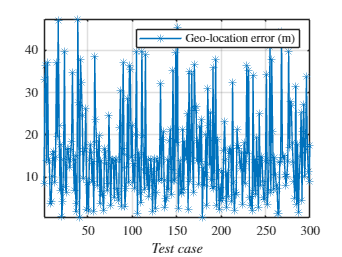

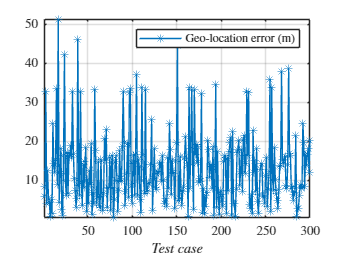

% fa = 1; cel = {tc, fa, idx, ci};
% [d11m, d12m] = dis(cel, p);
% save(ad,"ir","-append") %

figure; plot(d1km(:, 1),'-*'); axis tight
xlabel('$Test$ $case$','interpreter','latex')
legend('Geo-location error (m)', ...
'interpreter','latex'); axe(); grid on
% ylabel('Geo-location error (in meters)', ...
% 'interpreter','latex')
% print(fig,'DistG','-djpeg')
% title('distance(Km)')

figure; plot(d1km(:, 2),'-*');
axis tight; axe(); grid on
xlabel('$Test$ $case$','interpreter','latex')
legend('Geo-location error (m)', ...
'interpreter','latex')
% ylabel('Geo-location error (in meters)', ...
% 'interpreter','latex')
% print(fig,'DistG','-djpeg')
%title('distance(Km)')

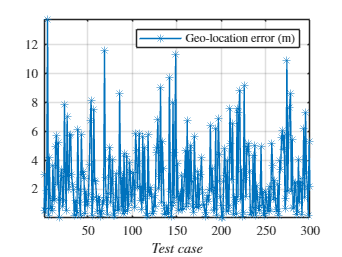

figure; plot(d1km(:, 1),'-*'); axis tight
xlabel('$Test$ $case$','interpreter','latex')
legend('Geo-location error (m)', ...
'interpreter','latex'); axe(); grid on
% ylabel('Geo-location error (in meters)', ...
% 'interpreter','latex')
% print(fig,'DistG','-djpeg')
%title('distance(Km)')

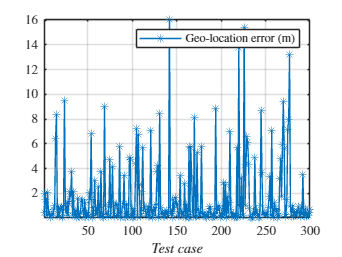

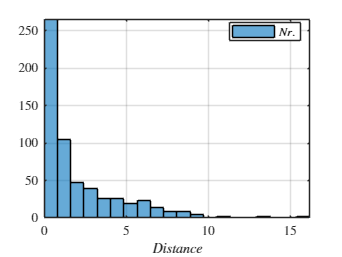

figure; plot(d1km(:, 2),'-*');
axis tight
xlabel('$Test$ $case$','interpreter','latex')
legend('Geo-location error (m)', ...
'interpreter','latex')
% ylabel('Geo-location error (in meters)', ...
% 'interpreter','latex')
% print(fig,'DistG','-djpeg')
grid on; axe() %title('distance(Km)')

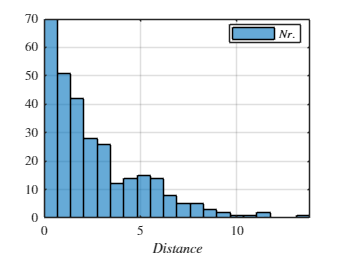

% print(fig,'Ca','-djpeg')
figure; histogram(d1km(:, 1),20)
xlabel('$Distance$','interpreter','latex'); axe()
legend({'$Nr.$'}, 'Location', 'Best', ...
'interpreter', 'latex'); axis tight; grid on
% title(['$SNR = $',num2str(so)], ...
% 'interpreter','latex')

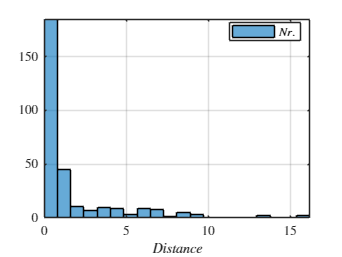

% print(fig,'Ca','-djpeg')
figure; histogram(d1km(:, 2),20)
xlabel('$Distance$','interpreter','latex'); axe()
grid on
legend({'$Nr.$'}, 'Location', 'Best', ...
'interpreter', 'latex');
% title(['$SNR = $',num2str(so)], ...
% 'interpreter','latex')
axis tight

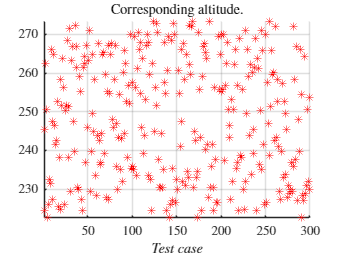

figure;
scatter(1:300, tc{1,2}.Altitude(:),'r*');
xlabel('$Test$ $case$','interpreter','latex');axe()
% ylabel('')
grid on; title('Corresponding altitude.', ...
'interpreter','latex'); axis tight

% kh = cell(2,1);
% for r = 1:2
%     t = tc{r, 2}
%     kh = t(:, 1).Variables;
%     ntla(:, 1).Variables = awgn(kh,sh,
% 'measured');
%     ntl(:, 1).Variables = ntla(:, 1).Variables;
% end

t = tc{1, 2}; ntla = t; sh = 60; % 70;
kh = t(:, 1).Variables;
ka = t(:, 2).Variables; snr = 55; % sh
k = t(:, 3).Variables; so = snr+20; % - 20 + 20

ntla(:, 1).Variables = awgn(kh,sh,'measured');
% ntl(:, 1).Variables = ntla(:, 1).Variables;
ntla(:, 2).Variables = awgn(ka,snr,'measured');
% ntl(:, 2).Variables = ntla(:, 2).Variables;
ntla(:, 3).Variables = awgn(k,so,'measured');

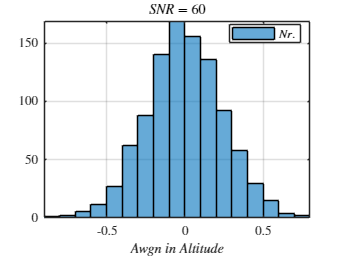

% sh = 60;
figure;
histogram(kh - n(:,1).Variables); axis tight
xlabel('\it Awgn in Altitude','interpreter', ...
    'latex'); grid on
legend({'$Nr.$'}, 'Location','Best', ...
    'interpreter','latex');
title(['$SNR = $',num2str(sh)], ...
    'interpreter','latex'); axe()

% '$\frac{d}{dx}sin(x)$';
% print(fig,'Ha','-djpeg')

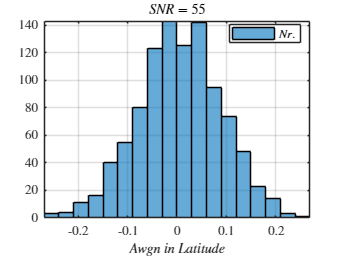

% snr = 60;
figure;
histogram(ka - n(:,2).Variables); axis tight
xlabel('\it Awgn in Latitude','interpreter', ...
    'latex'); grid on
legend({'$Nr.$'}, 'Location','Best', ...
    'interpreter','latex'); % 'northwest'
title(['$SNR = $',num2str(snr)], ...
    'interpreter','latex'); axe()

% print(fig,'Hla','-djpeg')

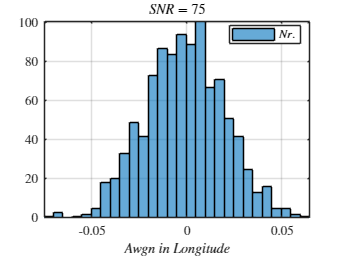

% so = snr+20;%-10;
figure;
histogram(o - n(:,3).Variables); axis tight
xlabel('\it Awgn in Longitude','interpreter', ...
    'latex'); grid on
legend({'$Nr.$'}, 'Location','Best', ...
    'interpreter', 'latex');
title(['$SNR = $',num2str(so)], ...
    'interpreter','latex'); axe()

% print(fig,'Ho','-djpeg')

fprintf(['Drone data, output: Latitude\n' ...
    '8 of ' num2str(length(n(:,1).Variables) ...
    ) ' rows, 3 of 6 cols']); n(1:8,:)

Drone data, output: Latitude
8 of 1000 rows, 3 of 6 cols

ans = 8x6 table
    Altitude    Latitude    Longitude    PixelX    PixelY    Ylatitude
    ________    ________    _________    ______    ______    _________

     222.18      47.583      -122.16      236       190       47.643  
     224.19      47.613      -122.13      236       191       47.643  
     224.52      47.722      -122.13      236       191       47.643  
     224.71      47.588      -122.11      236       191       47.643  
     225.58      47.769      -122.13      236       192       47.643  
     226.37      47.522      -122.11      236       192       47.643  
     226.25      47.798      -122.12      236       192       47.643  
      226.8      47.653       -122.1      236       193       47.643  


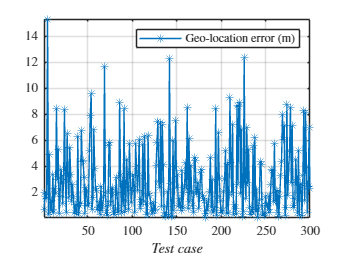

figure; plot(d1km(:, 1),'-*');
axis tight
xlabel('$Test$ $case$','interpreter','latex')
legend('Geo-location error (m)', ...
'interpreter','latex')
% ylabel('Geo-location error (in meters)', ...
% 'interpreter','latex')
axe()
% print(fig,'DistG','-djpeg')
grid on %title('distance(Km)')

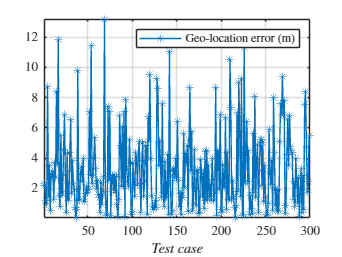

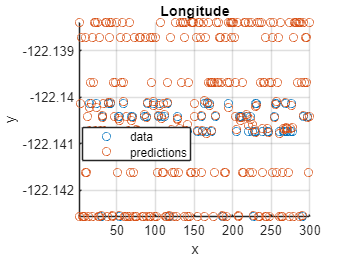

figure; plot(d1km(:, 2),'-*');
axis tight
xlabel('$Test$ $case$','interpreter','latex')
legend('Geo-location error (m)', ...
'interpreter','latex')
% ylabel('Geo-location error (in meters)', ...
% 'interpreter','latex')
axe()
% print(fig,'DistG','-djpeg')
grid on %title('distance(Km)')

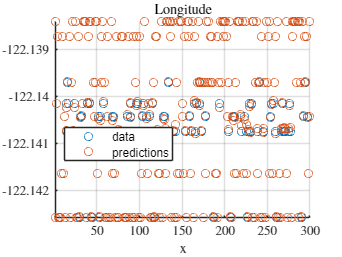

figure(); t = nt{2, 2}; scatter(1:300, t(:, ...
    end).Variables);
% tlltr(1:tr-1,"Ylongitude").Ylongitude
axis tight; xlabel('x','interpreter','latex');
% ylabel('y');
hold on;
scatter(1:300, pt(:,2,2)/10); hold off; grid on
legend({'data','predictions'}, ...
    'Location','Best');
title('Longitude','interpreter','latex'); axe()

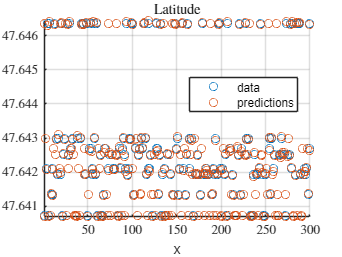

figure(); t = nt{1, 2}; scatter(1:300, t(:, ...
    end).Variables);
% tlltr(1:tr-1,"Ylongitude").Ylongitude
axis tight; xlabel('x');
% ylabel('y');
hold on;
scatter(1:300, pt(:,1,2)/10); hold off; grid on
legend({'data','predictions'}, ...
    'Location','Best');
title('Latitude','interpreter','latex'); axe()

[m, i] = min(d1km);
[M, I] = max(d1km); {m(1), M(1), m(2), M(2);
                     i(1), I(1), i(2), I(2)}'

ans = 4x2 cell array
    {[ 0.1261]}    {[ 35]}
    {[13.3737]}    {[ 54]}
    {[ 0.0669]}    {[242]}
    {[14.6186]}    {[ 54]}


fig = figure; histogram(d1km)
xlabel('Distance','interpreter','latex')
grid on; legend({'$Nr.$'}, 'Location', 'Best', ...
    'interpreter', 'latex'); axis tight
% title(['$SNR = $',num2str(so)], ...
    % 'interpreter','latex')

% print(fig,'Hdist','-djpeg')

% find(i==in)

ans =     38
   336


% m = [find(i==in),find(I==in)]

m =     38   194
   336   494


% [m, i] = min(sort(d1km));
% [M, I] = max(sort(d1km)); {m(1), M(1), m(2),
% M(2);
%                      i(1), I(1), i(2), I(2)}'

## M2

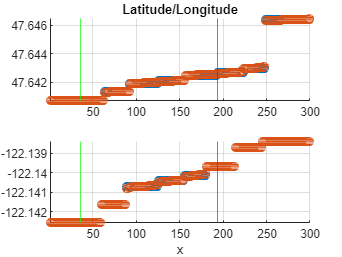

figure(); subplot(2,1,1); t = nt{1, 2};
scatter(1:300, sort(t(:, end).Variables));
% plot(tlts(:, ...
%     end).Variables);
% tlltr(1:tr-1,"Ylongitude").Ylongitude
axis tight; hold on; [s, in] = sort(pt(:,1,2)/10);
scatter(1:300, s); hold off;
grid on
% legend({'dataA','predA'}, ...
%     'Location','Best');
title('Latitude/Longitude');
m2 = [find(I(2)==in); find(i(2)==in)];
xline(m2(2), 'g'); xline(m2(1), 'r')

subplot(2,1,2);
 t = nt{2, 2}; scatter(1:300, sort(t(:, ...
    end).Variables)); axis tight; xlabel('x')
hold on;
scatter(1:300, sort(pt(:,2,2)/10)); hold off;
grid on
% legend({'dataL','predL'}, ...
%     'Location','Best');
xline(m2(2), 'g'); xline(m2(1), 'r')

function [m, t] = dtl(d1m)
    m = zeros(4, 5);
    for co = 1:5
        [m(1, co), m(2, co)] = min(d1m(:, co));
        [m(3, co), m(4, co)] = max(d1m(:, co));
    end
    t = table(round(m(1, :),2)', m(2, :)',...
        round(m(3, :),2)',...
        m(4, :)','VariableNames',{...
    'Min','Im','Max','IM'});
end
function [d1km, d2km] = dis(cel, p)
    tr = max(size(cel{1}{1}))+1;
    % 100*cel{2}+1; 
    idx = cel{3}; % c/c
    ci = cel{4}; l = max(size(cel{1}));
    d1km = zeros(tr-1, l); d2km = d1km; c = cel{1};
    for co = 1:l
        for i = 1:tr-1
            [d1km(i, co), d2km(i, co)] = ...
                lldistkm(...
                [c{1,idx(ci(co))}.Ylatitude(i...
                ) c{2,idx(ci(co))}.Ylongitude(i...
                )], [p(i,1,co) p(i,2,co)]);
        end
    end
    d1km = d1km*1000; d2km = d2km*1000; % m
end
function axe()
    axes = gca;
    axes.XAxis.TickLabelInterpreter = 'latex';
    axes.YAxis.TickLabelInterpreter = 'latex';
end